birdID = 'TURMER';

directoryPath = sprintf('samples/syllables/%s',birdID);
fileList = dir(fullfile(directoryPath, '*.wav'));

samples = cell(numel(fileList), 2);
for i = 1:numel(fileList)
    filePath = fullfile(directoryPath, fileList(i).name);
    [signal, fs] = audioread(filePath);
    samples(i,:) = {signal, fs};
end

filtBanks.fs44100 = gammatoneFilterBank([50 20000],64,44100);
X = zeros(size(samples,1),256*34);
padFrames = 15000;

for ii = 1:size(samples,1)
    signal = samples{ii,1};
    fs = samples{ii,2};
    filtBankKey = sprintf('fs%d',fs);
    if isfield(filtBanks,filtBankKey)
        gt = filtBanks.(filtBankKey);
    else
        gt = gammatoneFilterBank([50 20000],64,fs);
        filtBanks.(filtBankKey) = gt;
    end
    X(ii,:) = extractMrcgFeature(gt,signal,fs,15000);
end

SVMModel = fitcsvm(X,ones(size(X,1),1),'KernelFunction','rbf',...
    'Standardize',true);

minVal = min(X,[],'all');
maxVal = max(X,[],'all');
rubbish = minVal + (maxVal-minVal)*rand(200,8704);
[label,score] = predict(SVMModel,[X;rubbish]);

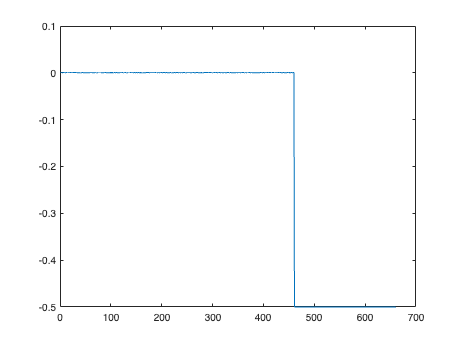

plot(1:660,score)

### **Test on unseen Blackbird sounds**

[audio,fs] = audioread('samples/common_blackbird_short1.wav');
audio = mono(audio);
audio = stripSound(audio,fs);

syllables = segmentSyllables(audio,fs);

XTest = zeros(size(syllables,1),8704);
for i = 1:size(syllables,1)
    XTest(i,:) = extractMrcgFeature(gt,syllable,fs);
end

[label,score] = predict(SVMModel,[XTest]);

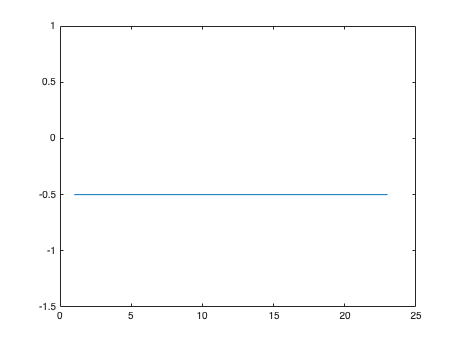

plot(1:size(score,1),score)